# **demo04 of Im2mesh package**

demo04 - What is inside function im2mesh.

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Shape

Let's start demo. Import image Shape.tif.

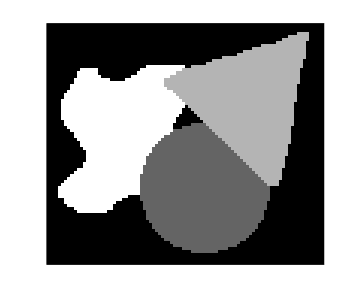

im = imread("Shape.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## Extract boundaries

We use function im2Bounds to extract boundaries.

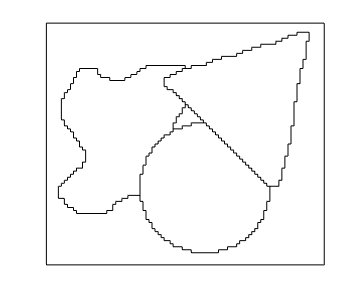

% image to polygon boundary
boundsRaw = im2Bounds( im );
% plot boundary using plotBounds
plotBounds(boundsRaw);

We can use function totalNumVertex to get total number of vertices in boundsRaw.

totalNumVertex(boundsRaw)

ans = 1320

## Find control points

We use function getCtrlPnts to find and label control points.

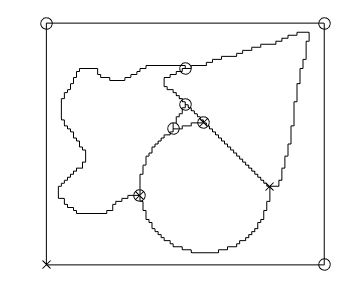

% label control points
tf_avoid_sharp_corner = false;
boundsCtrlP = getCtrlPnts( boundsRaw, tf_avoid_sharp_corner, size(im) );

plotBounds(boundsCtrlP, true);     % show starting and control points

We can use function totalNumCtrlPnt to get total number of control points.

totalNumCtrlPnt(boundsCtrlP)

ans = 22

## Smooth boundary

We use function smoothBounds to smooth boundary.

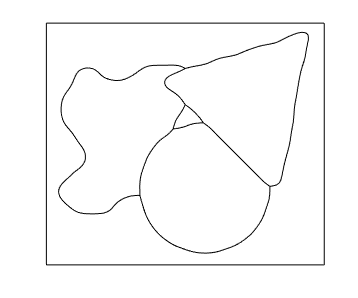

lambda = 0.5;
mu = -0.5;
iters = 100;
threshold_num_turning = 0;
threshold_num_vert_Smo = 0;

boundsSmooth = smoothBounds( boundsCtrlP, lambda, mu, iters, ...
                threshold_num_turning, threshold_num_vert_Smo );

plotBounds(boundsSmooth);

## Simplify boundary

We use function simplifyBounds to simplify boundary. Other operation shown here is used to clear up redundant vertices.

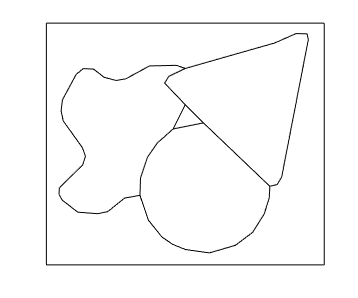

% simplify polygon boundary
tolerance = 0.5;
threshold_num_vert_Sim = 0;
boundsSimplified = simplifyBounds( boundsSmooth, tolerance, ...
                                        threshold_num_vert_Sim );
boundsSimplified = delZeroAreaPoly( boundsSimplified );

% clear up redundant vertices
% only control points and turning points will remain
boundsClear = getCtrlPnts( boundsSimplified, false );
boundsClear = simplifyBounds( boundsClear, 0 );

plotBounds(boundsClear);

We can use function totalNumVertex to get total number of vertices in boundsClear.

totalNumVertex(boundsClear)

ans = 104

## Generate mesh

We can use function getPolyNodeEdge to get the nodes and edges of polygonal boundary. Then, we can use function poly2mesh to generate mesh. Function poly2mesh is using MESH2D as mesh generator.

grad_limit = 0.25;
hmax = 500;
mesh_kind = 'delaunay';

% get nodes and edges of polygonal boundary
[ poly_node, poly_edge ] = getPolyNodeEdge( boundsClear );

% generate triangular mesh
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, ...
                            hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                 81                 96
         10                 95                205
         10                 95                205


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          9                149                 96
         10                149                234
         16                161                716


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                168                712
          8                 14                712



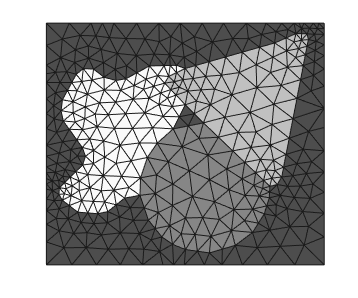

% plot mesh using function plotMeshes
plotMeshes(vert,tria,tnum)

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo